# Get Started with ROS 2

Robot Operating System 2 (ROS 2) is the second version of ROS, which is a communication interface that enables different parts of a robot system to discover, send, and receive data. MATLAB® support for ROS 2  is a library of functions that allows you to exchange data with ROS 2 enabled physical robots or robot simulators such as Gazebo®. ROS 2 is built on Data Distribution Standard (DDS) which is an end-to-end middleware that provides features such as discovery*, *serialization and transportation. These features align with the design principles of ROS 2 such as* distributed discovery* and control over different *"Quality of Service"* options for transportation. DDS uses Real Time Publish-Subscribe (RTPS) protocol which provides communication over unreliable network protocols such as UDP. For more information, see [RTPS](https://fast-rtps.docs.eprosima.com/en/latest/).

This example shows how to:

- Set up ROS 2 within MATLAB

- Get information about capabilities in a ROS 2 network

- Get information about ROS 2 messages

To learn about ROS, see [Get Started with ROS](docid:ros_ug.mw_cb3fdf75-613d-45b1-90e1-aad102b9a24a).

## ROS 2 Terminology

- A *ROS 2 network* comprises different parts of a robot system (such as a planner or a camera interface) that communicate over ROS 2 network. The network can be distributed over several machines.

- A *ROS 2 node* is an entity that contains a collection of related ROS 2 capabilities (such as publishers and subscribers). A ROS 2 network can have many ROS 2 nodes.

- *Publishers *and *subscribers* are different kinds of ROS 2 entities that process data. They exchange data using *messages*.

- A publisher sends messages to a specific *topic* (such as "odometry"), and subscribers to that topic receive those messages. There can be multiple publishers and subscribers associated with a single topic.

- A* Domain  *is the physical segmentation of network. It is identified by a unique integer value known as *Domain ID.* By default the* Domain ID* is `0`.

- Every node in ROS 2 network on creation advertises its presence to other nodes in the same *Domain ID *only*.*

- *ROS 2 *network is built on Data Distribution Standard (DDS) which makes it possible to connect multiple nodes across distributed network.

- *RTPS* (Real Time publisher-subscriber) protocol provides ROS 2 network with capabilities to send messages in unreliable network conditions.

- ROS 2 offers variety of *Quality of Service (QoS)* policies that allow you to tune your communication between nodes. For more information, see [Manage Quality of Service Policies in ROS 2](docid:ros_ug.mw_3b9736f5-c51a-4537-b4ae-333759ca4d41).

For more information, see [Robot Operating System2  (ROS 2)](https://index.ros.org/doc/ros2/) and the [Concepts](https://index.ros.org//doc/ros2/Concepts/Overview-of-ROS-2-concepts/) section on the ROS 2 website. 

## Initialize ROS 2 Network

Unlike ROS, ROS 2 does not require initialization in MATLAB. The ROS 2 network automatically starts with creation of nodes.

Use `ros2node` to create a node.

test1 = ros2node("/test1")

Use `ros2 node list` to see all nodes in the ROS 2 network.

ros2 node list

Use `clear `to shutdown the node in ROS 2 network.

clear test1

Use `exampleHelperROS2CreateSampleNetwork` to populate the ROS network with three additional nodes with sample publishers and subscribers.

exampleHelperROS2CreateSampleNetwork

Use `ros2 node list` again, and observe that there are three new nodes, `node_1`, `node_2`, and `node_3`).

ros2 node list

A visual representation of the current state of the ROS 2 network is shown below. Use it as a reference when you explore this sample network in the remainder of the example.

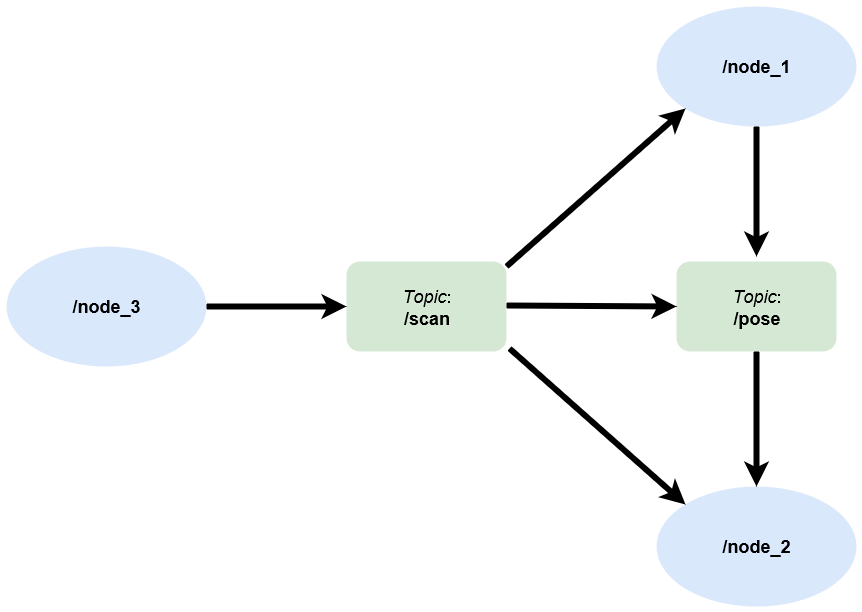

## Topics

Use `ros2 topic list` to see available topics in the ROS 2 network. Observe that there are four active topics: `/pose`, `/clock`, `/parameter_events` and `/scan`.The topics /`clock `and `/parameter_events `are global topics which always present in the ROS 2 network. Topic `/clock` is used for synchronization whereas topic /`parameter_events `is used by nodes to monitor or change parameters in the network. The other two topics /`scan `and /`pose` were created as part of the sample network.

ros2 topic list

Each topic is associated with a m*essage type*. Use `ros2 topic list -t ` to see the message type of the topics.

ros2 topic list -t

## Messages

Publishers and subscribers use ROS 2 messages to exchange information. Each ROS 2 message has an associated message type that defines the datatypes and layout of information in that message. For more information, see [Work with  Basic ROS 2 Messages](docid:ros_ug.mw_8a48f84f-f79b-4aa6-8163-a8ef53743751).

Use `ros2 msg show` to view the properties of a message type. The `geometry_msgs/Twist` message type has two properties, `Linear` and `Angular`. Each property is a message of type `geometry_msgs/Vector3`, which in turn has three properties of type `double`.

ros2 msg show geometry_msgs/Twist
ros2 msg show geometry_msgs/Vector3

Use` ros2 msg list` to see the full list of message types available in MATLAB.

## Disconnect From ROS 2  Network

Use `exampleHelperROS2ShutDownSampleNetwork` to remove the sample nodes, publishers, and subscribers from the ROS 2 network. To remove your own nodes, use `clear` with the node, publisher, or subscriber object.

exampleHelperROS2ShutDownSampleNetwork

## Next Steps

- [Connect to a ROS 2 Network](docid:ros_ug.mw_ef69ae07-7234-49b7-b384-86c479d401fd)

*Copyright 2019 The MathWorks, Inc.*